# Joint Lip Tongue 5-mechanism plus blood search

This is a sequential fitting approach.  It is applied to the full 500-700 nm range.

## Stage 1 (oeSolveJoint).

We fix a matrix with collagen1-smooth, FAD_webfluor, porphyrin and chlorophyll excitations. We choose these four because the first two fit the lip data well.  This guarantees that we will be able to find a fit to the lip data at the end.

We use oeSolveJoint to do two things.  

- Vary the blood oxygen of collagen, and 

- Search for one more, additional fluorophore, specified only as a skewed Gaussian with three parameters (mean, width, skew), to improve the fit. 

The additional (fifth) fluorophore is a stand-in for keratin, which is present on the tongue, but not on the lip.  We call this estimated fluorophore pseudo-keratin.

In the initial stage of the fit, we use the same blood density for all subjects.  The purpose of this stage is to learn about the parameters of the skewed Gaussian, which we store and use later.

## Stage 2 (oeSolveBlood)

We confirm that we can fit the lip data with just the collagen and FAD, searching for blood.  This is for the group lipData.

## Stage 3 (oeSolveBlood)

We loop through the subjects.  

For the tongue, we use the five fluorophores (collagen, FAD, porphyrin, chlorophyll, pseudo-keratin) and solve for the blood in each subject.

For the lip, we use only two fluorophores (collagen, FAD) and solve for the blood in each subject.

ieInit;
wave = 500:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
fise_plotDefaults;
subjects = {'Z','B','D','J'};
[T,dataDir] = oeDatabaseCreate;

## Load up the lip and tongue data

Here, we load all of the subjects into a single large data set for tongue and another one for lip.  In this case we group the 405 and 415 nm excitation lights.  We put the tongue and lip data, normalized at nWave, on the same graph.  We fit these to find the pseudo-keratin.

tongueData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    tongueData = cat(2,tongueData,tmp);
end

lipData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
    lipData = cat(2,lipData,tmp);
end 


tongueData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave); 
    tongueData450 = cat(2,tongueData450,tmp);
end

lipData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);       
    lipData450 = cat(2,lipData450,tmp);
end 


## Create the fixed fluorophores

The first two worked for the lip very well from 500-700nm (see s_oeBloodFluorophoreLipSrch700.mlx).  For the tongue, we add porphyrin and chlorophyl (see s_oeBloodFluorophoreTongueSrch700.mlx).

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor','PorphyrinBjurshammar','chlorophyllA-7'};
[fixedFluorophores,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## Call the joint search

We have fluorophores for the lip that fit well if we adjust the blood density (per subject).  Those are collagen1-smooth and FAD_webfluor.  (Those are shown to work in s_oeBloodFluorophoreLipSrch700.mlx.) We fix those two fluorophores.  We also know the emission spectra of porphyrins and chlorophyll-a.  Those are contained in the fixedFluorophores variable.

We then estimate the emission spectrum of keratain. We do this by pooling the tongue data from all the subjects and searching for an additional basis term that is a skewed Gaussian and a blood density term. That fit from oeSolveJoint returns the discovered skewedGaussian as a column in the finalFluorophores matrix.We consider that term to be pseudo-keratin. The columns blood density to vary using those five terms (collagen1-smooth, FAD_webfluor, porphyrin, chlorophyll, pseudo-keratin).  

[global_params, weights, finalFluorophores] = oeSolveJoint(wave, tongueData, fixedFluorophores);
disp(global_params)

   11.2290  425.0961  386.6745    5.0000



savedFluorophores are the original fluorophores without blood and the newly estimated pseudo-keratin fluorophore. These are the fluorophores we use these later when we search for the blood density in individual subjects.

When we fit the tongue data, we use savedFluorophores for each subject separately and estimate their blood density.

When we fit the lip data, we do not use the last three fluorophores (porphyrins, chlorophyll-a, pseudo-keratin). 

savedFluorophores = [fixedFluorophores,finalFluorophores(:,end)];

%{
fname = fullfile(oeTongueLipRootPath,'data','savedFluorophores');
comment.txt = 'fluorophore basis with estimated keratin from oeFigure5_ModelFits';
comment.names = {'collagen1-smooth','FAD_webfluor','PorphyrinBjurshammar','chlorophyllA-7','pseudo-keratin'};

plotRadiance(wave,savedFluorophores);
legend(comment.names);
ieSaveSpectralFile(wave,savedFluorophores,comment,fname);
%}


## Show the fluorophores and blood incorporated

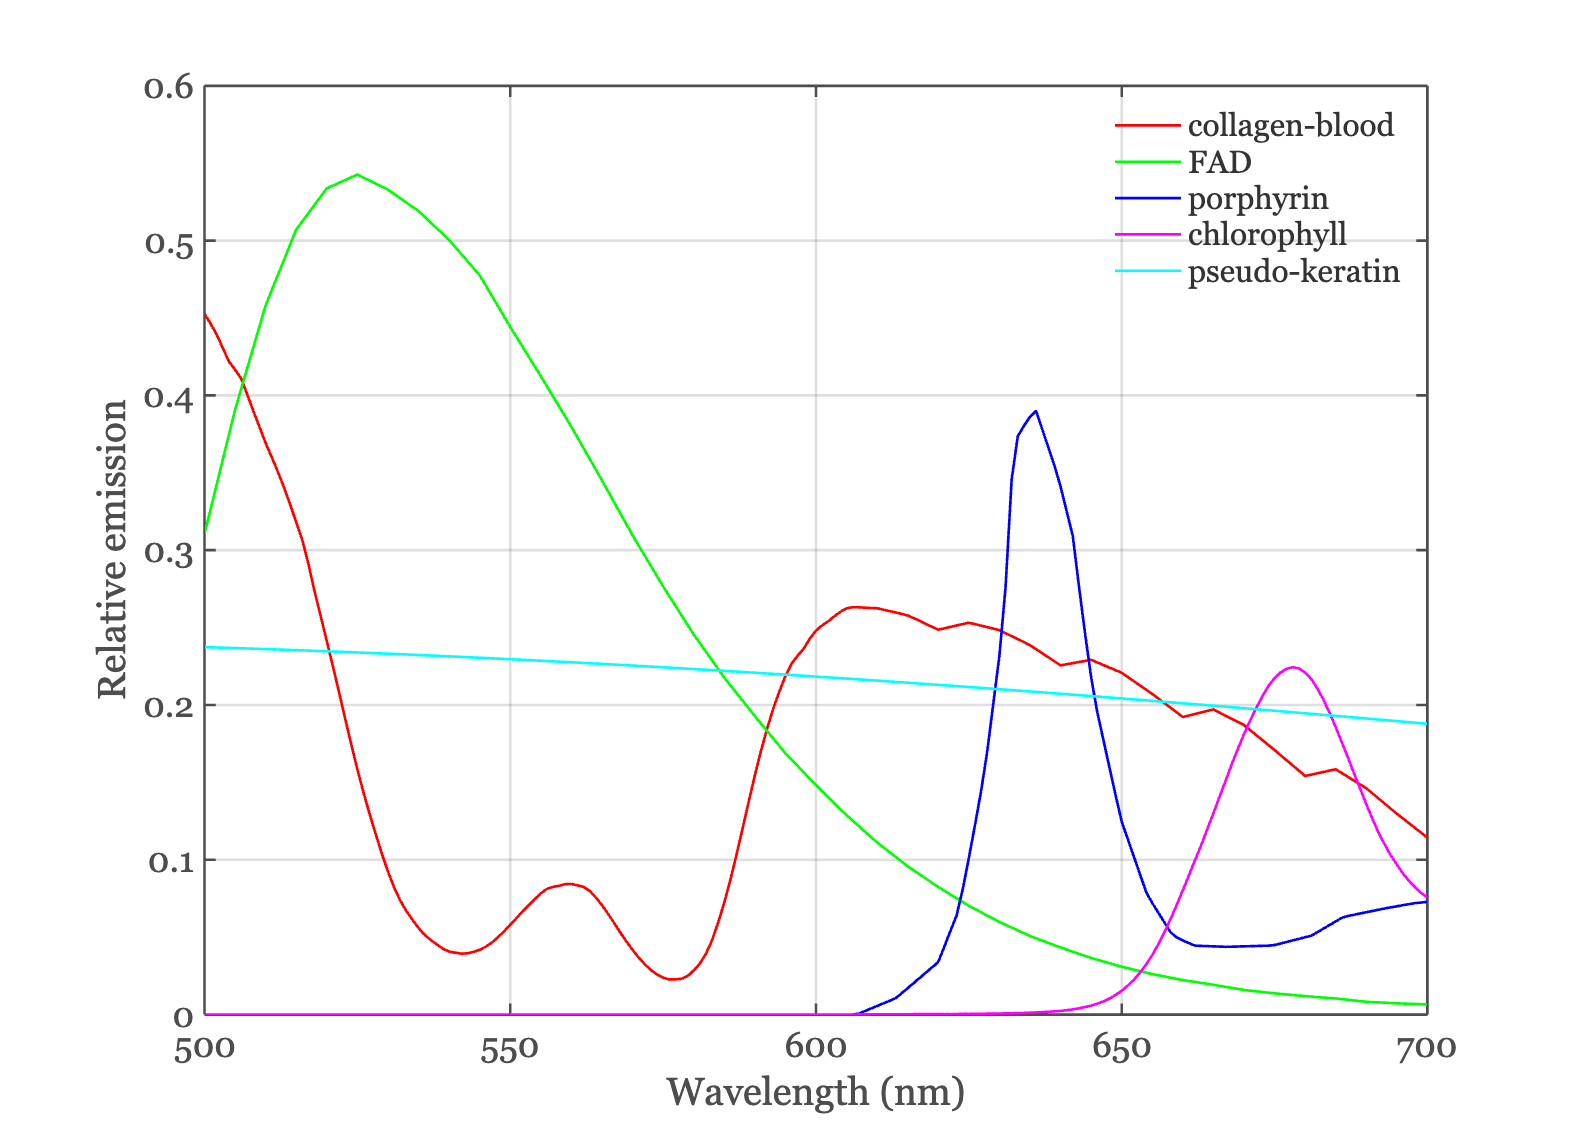

ieFigure;
plot(wave,finalFluorophores*diag(mean(weights,2)));
grid on; xlabel('Wavelength (nm)'); ylabel('Relative emission');
legend('collagen-blood','FAD','porphyrin','chlorophyll','pseudo-keratin');

## Show the predictions for the tongue data

These are the 405 nm and 415 nm fits.

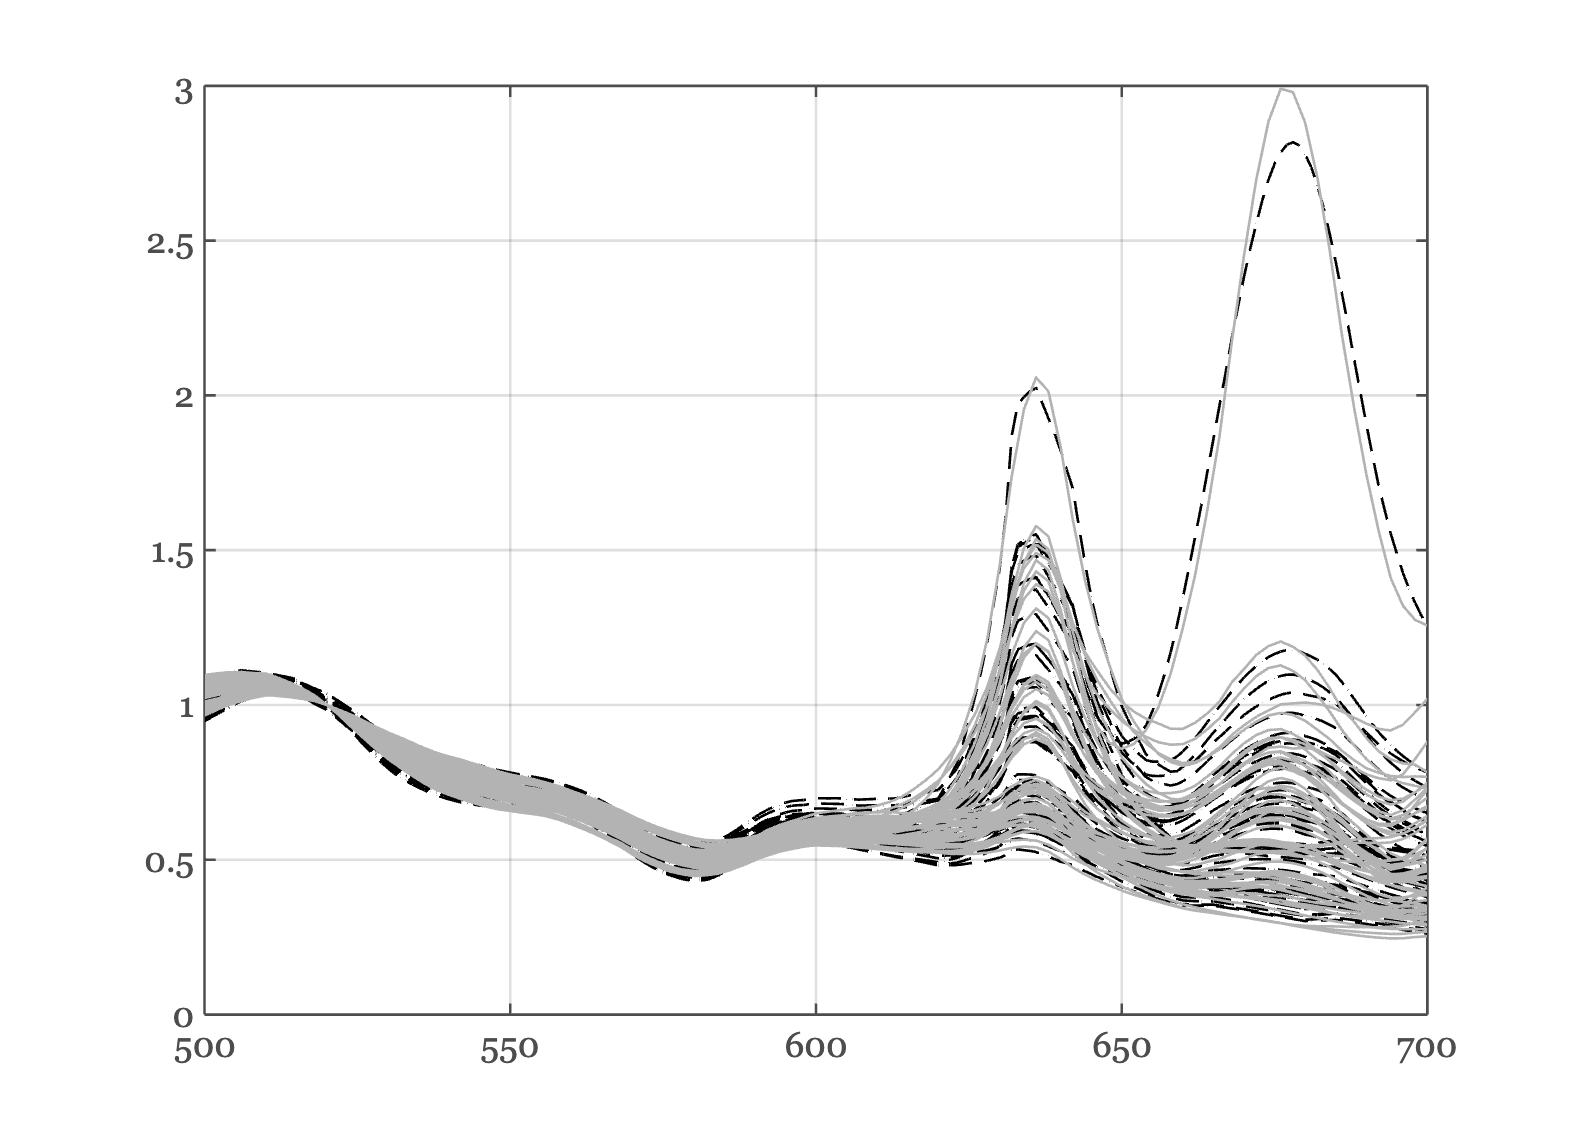

predicted = finalFluorophores*weights;
ieFigure; 
plot(wave,predicted,'k--'); hold on;
plot(wave,tongueData,'Color',[1 1 1]*0.7); grid on;

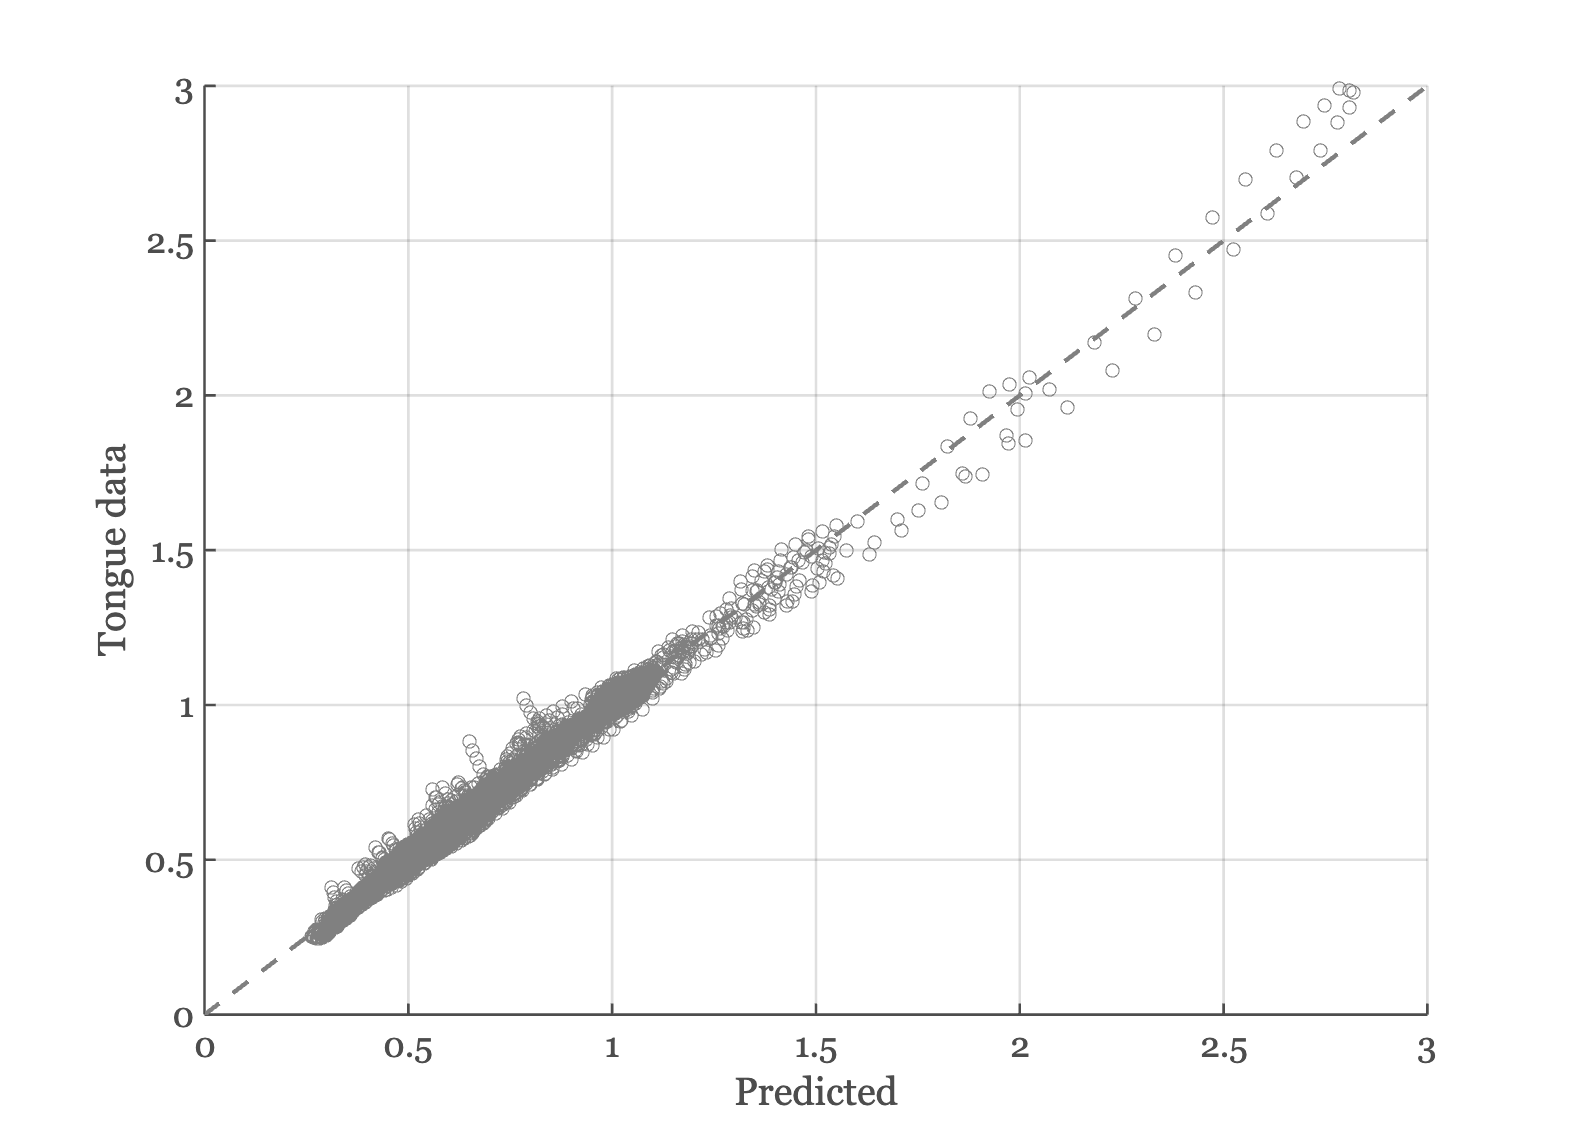

ieFigure;
hScatter = scatter(predicted(:),tongueData(:)); 
hScatter.CData = [1 1 1]*0.5;
xlabel('Predicted'); ylabel('Tongue data'); 
identityLine;

Here are the mean weights for the five different fluorophores when fit to the group tongue data.

mn = mean(weights,2);
fprintf('Collagen %.2f FAD %.2f Porphyrin %.2f Chlorophyll %0.2f PseudoKeratin %.2f\n',mn);

Collagen 10.43 FAD 0.54 Porphyrin 0.39 Chlorophyll 0.22 PseudoKeratin 0.30


## Fit the lip with a subset of fluorophores

We fit them using only the first two columns of the fixed fluorophores.  We just solve for the blood applied to the first column.  This step is not necessary, but it was a good check that we could approximate the group with a single blood optical density.

[od, weights,finalFluorophores] = oeSolveBlood(wave, lipData, fixedFluorophores(:,[1,2]));
fprintf('Blood density %.2f\n',od); ieFigure;

Blood density 8.63


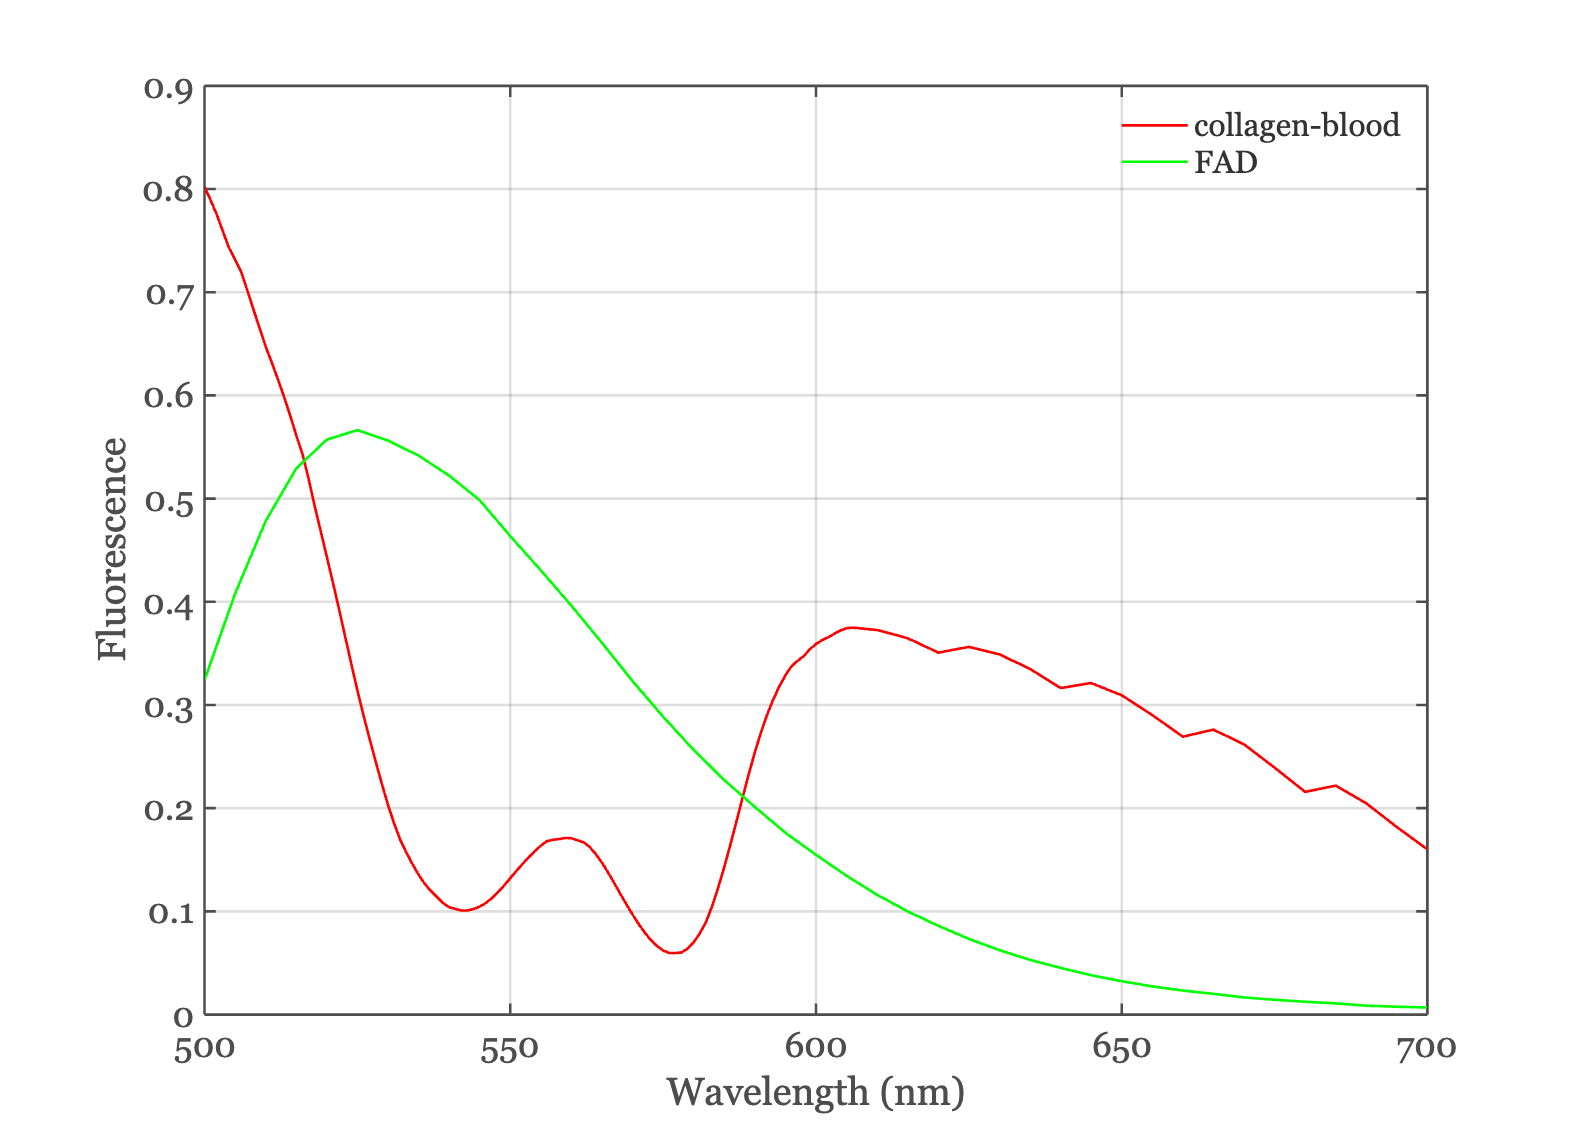

plot(wave,finalFluorophores*diag(mean(weights,2))); 
grid on; xlabel('Wavelength (nm)'); ylabel('Fluorescence');
legend('collagen-blood','FAD');

## Fits to lip 405 and 415

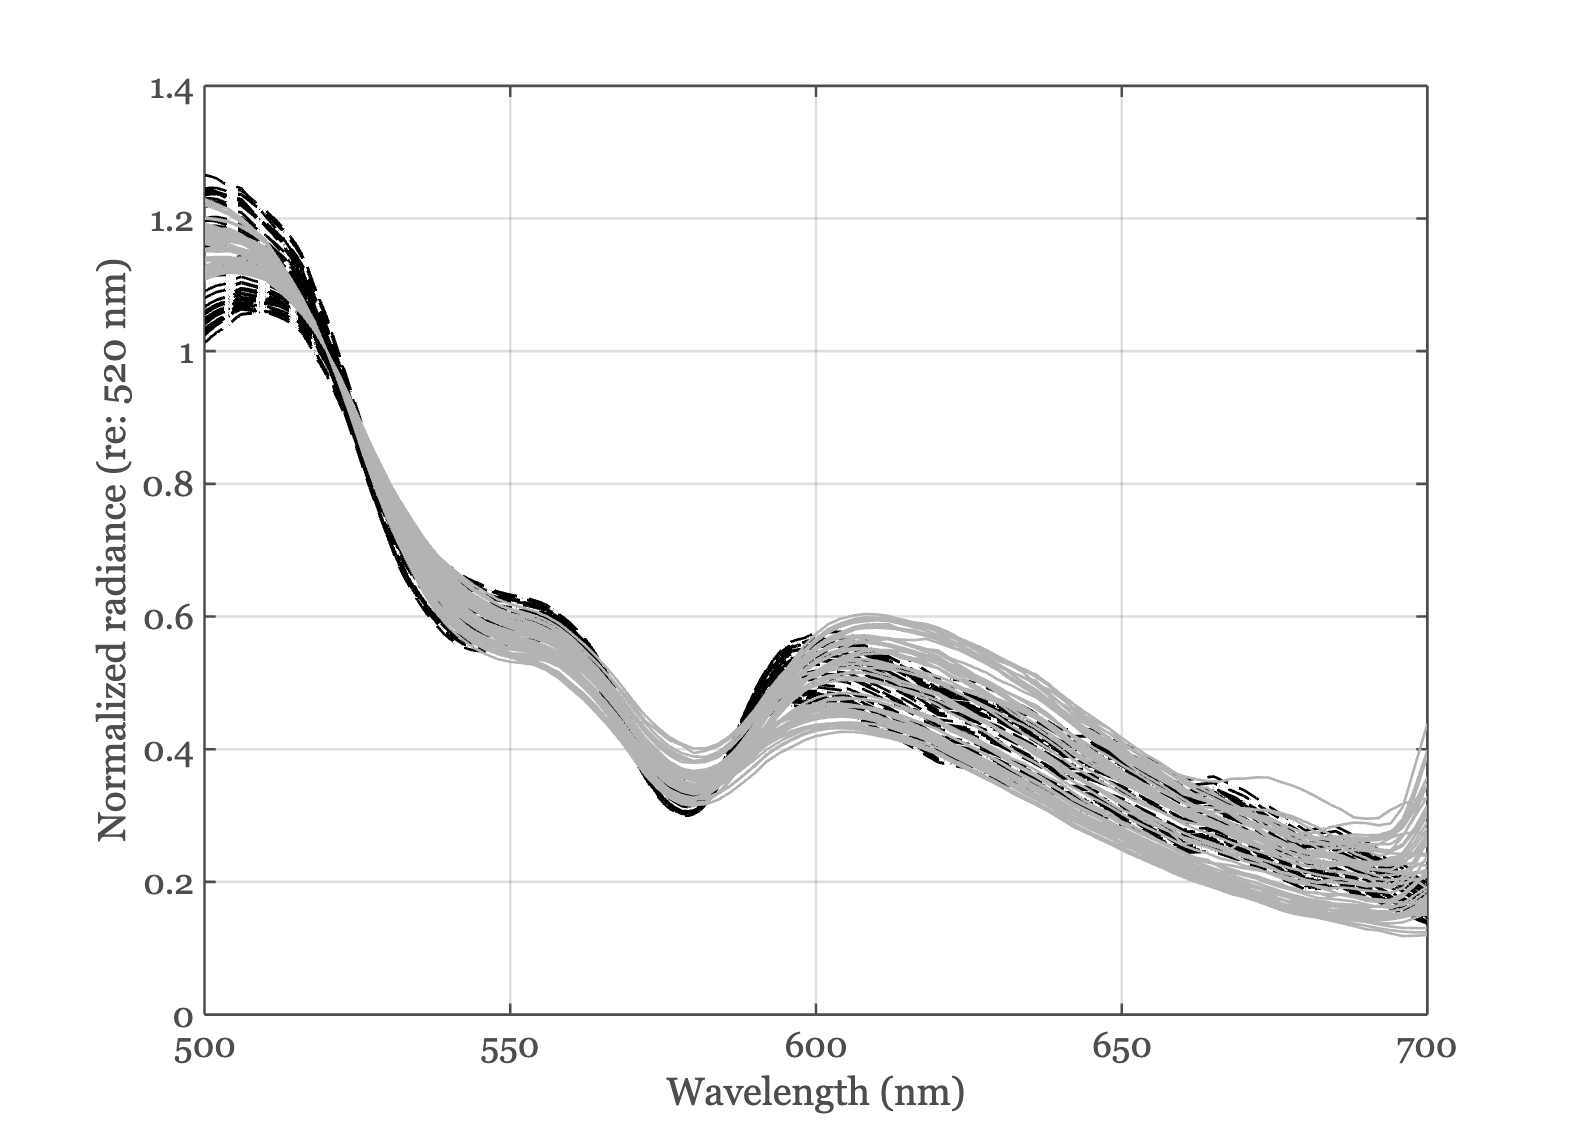

predicted = finalFluorophores*weights;
ieFigure; 
hA = plot(wave,predicted,'k--'); hold on;
hB = plot(wave,lipData,'Color',[1 1 1]*0.7); grid on; xlabel('Wavelength (nm)'); ylabel('Normalized radiance (re: 520 nm)')

Scatter plot to assess precision

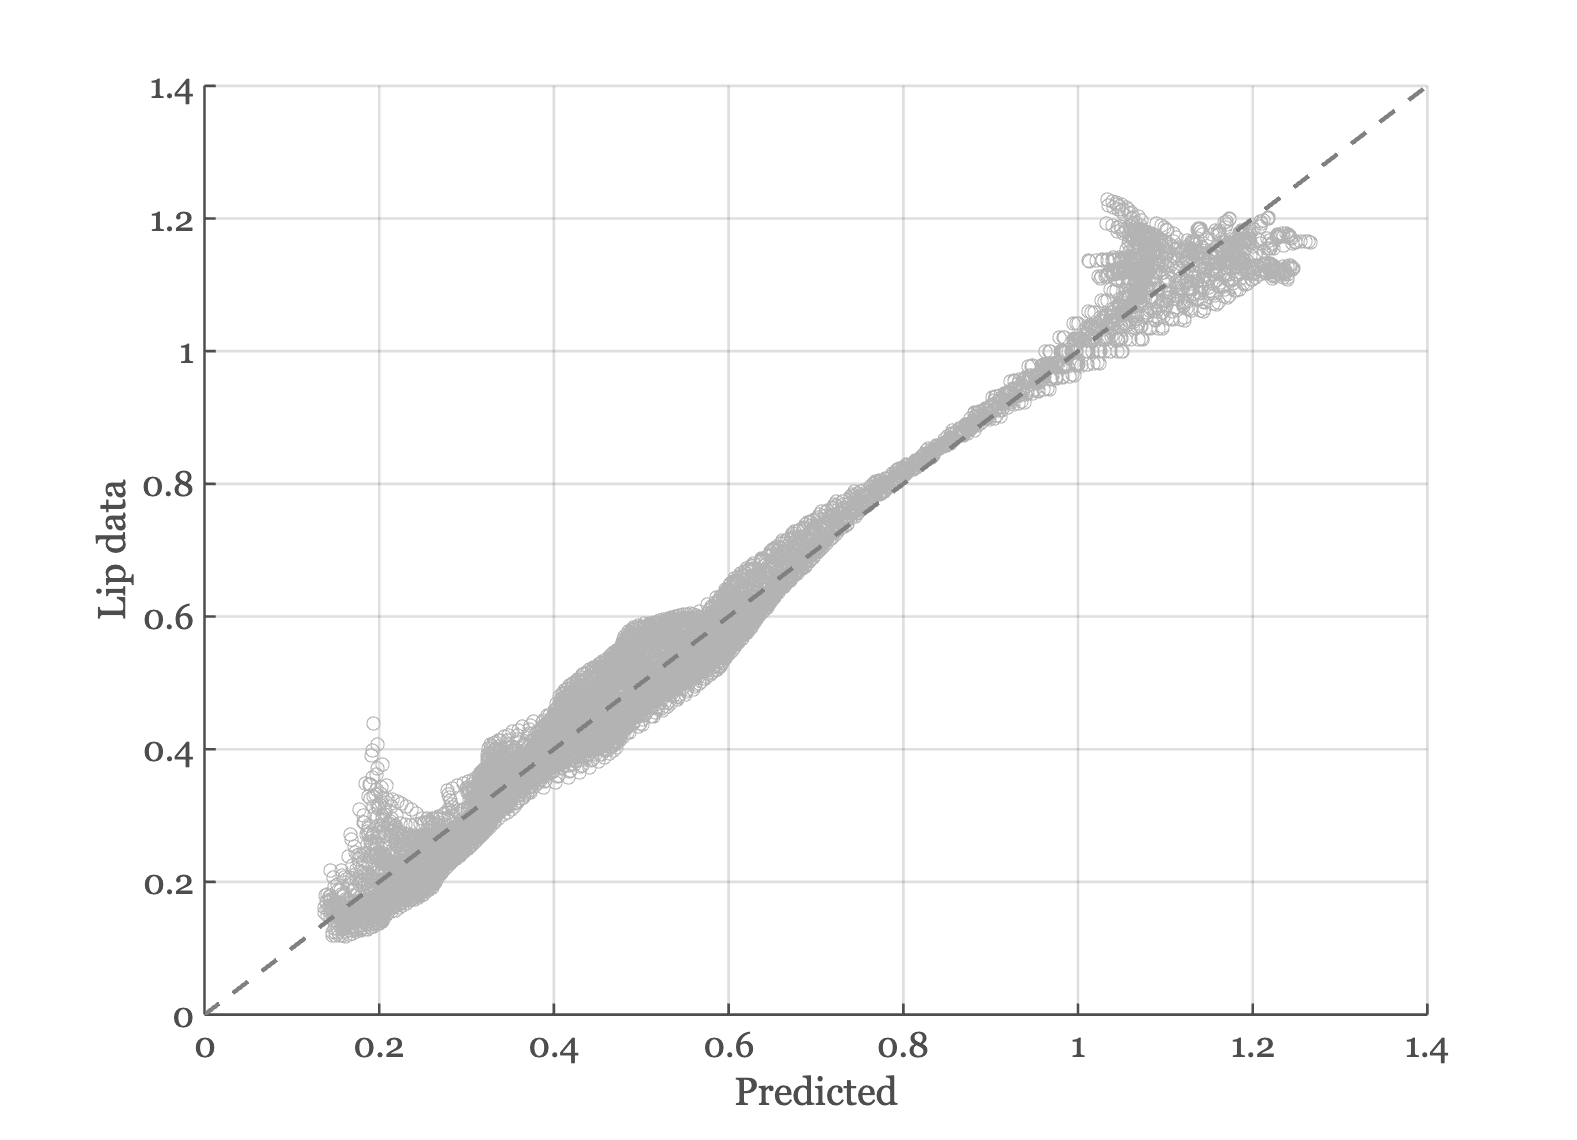

ieFigure;
hScatter = scatter(predicted(:),lipData(:),'o'); 
hScatter.CData = [1 1 1]*0.7;
identityLine; xlabel('Predicted'); ylabel('Lip data');

## Fit the subjects individually

For each subject, the tongue data with 405 and 415.  Use the five fluorophores to fit, adjusting only for the blood.

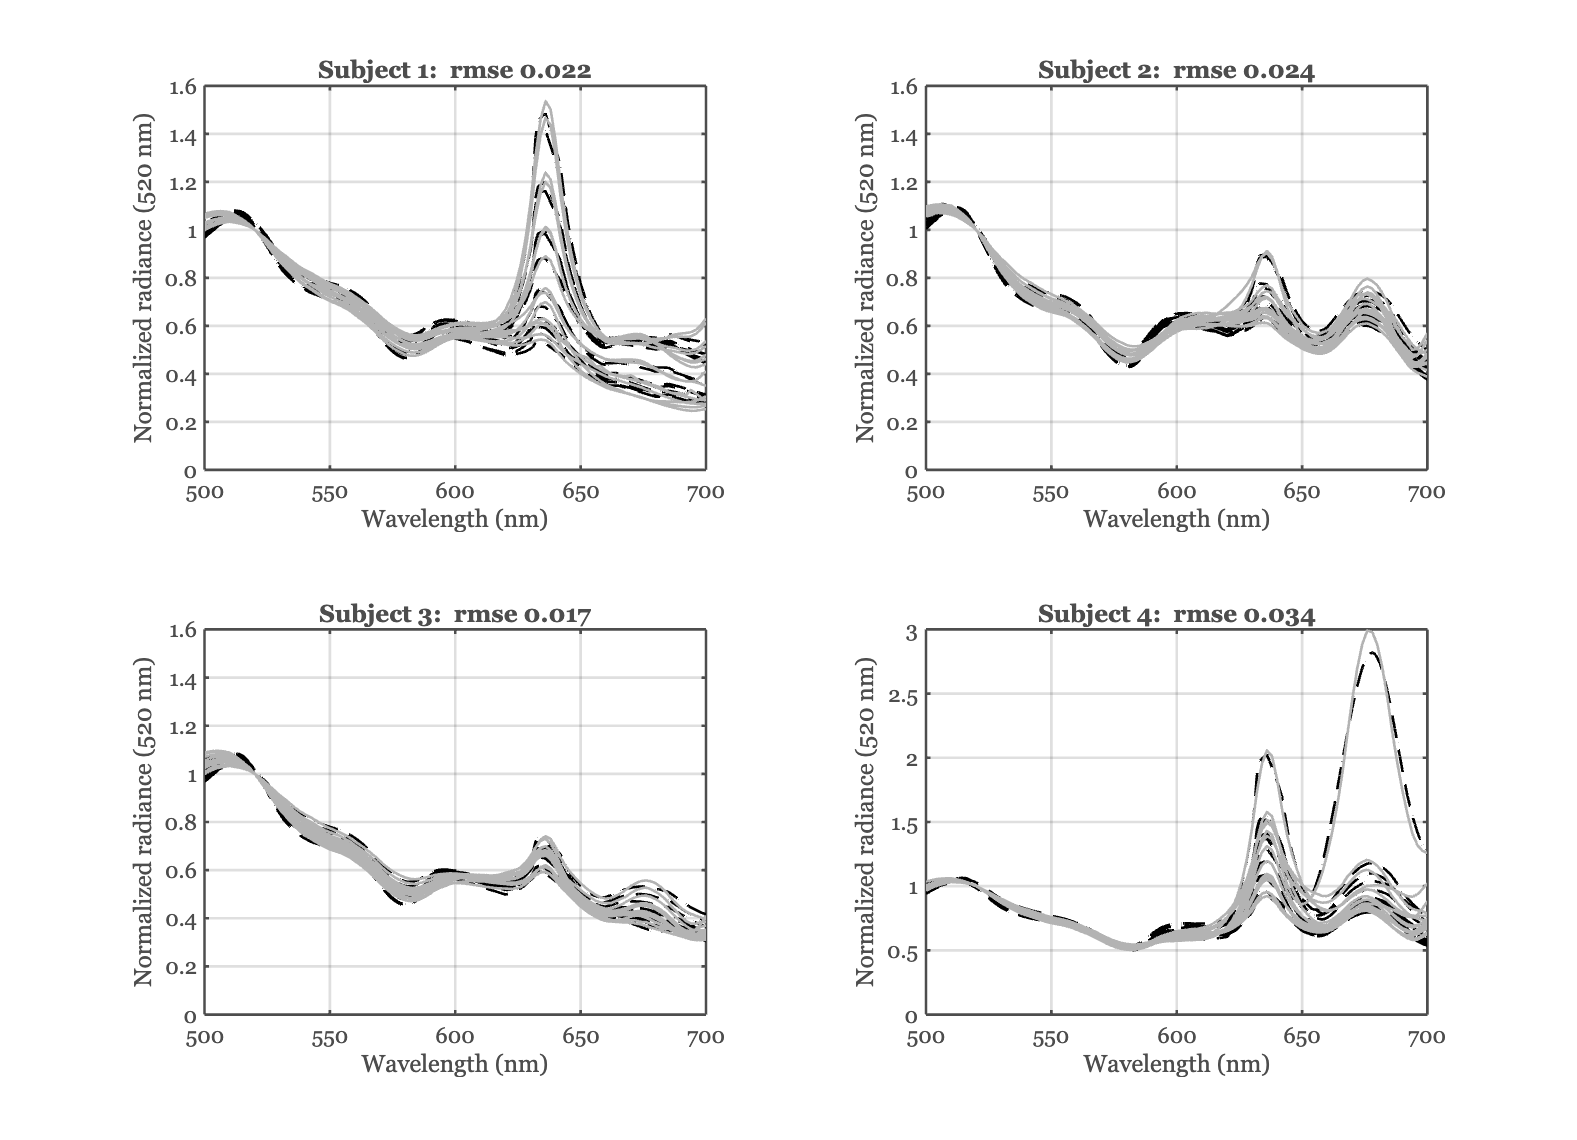

odTongue = zeros(1,numel(subjects));
weights = cell(4,1);
nTongue = zeros(1,numel(subjects));
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the tongue data
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    nTongue(ii) = size(tongueData,2);    

    % Find the blood optical density
    [odTongue(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,tongueData,savedFluorophores);
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,tongueData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance (520 nm)');
    set(gca,'ylim',[0 1.6]);
    if ii==4, set(gca,'ylim',[0 3]); end
    title(sprintf('Subject %d:  rmse %.3f',ii,rmse(tongueData(:),predicted(:))));
end
exportgraphics(gcf,'IndividualFits-tongue.png','Resolution',150);

## Table of the tongue weights and blood od

Print the mean of the weights and the standard deviation

fluorophoreNames = ["Collagen", "FAD", "Keratin", "Porphyrin", "Chlorophyll-a"];
oePrintModel(fluorophoreNames,odTongue,weights,nTongue);

Subject 1 (N=15):
Blood od 9.97  Collagen: 8.69 ± 1.07 FAD: 0.55 ± 0.05 Keratin: 0.42 ± 0.29 Porphyrin: 0.04 ± 0.04 Chlorophyll-a: 0.32 ± 0.08 

Subject 2 (N=14):
Blood od 11.75  Collagen: 13.18 ± 1.05 FAD: 0.55 ± 0.02 Keratin: 0.20 ± 0.09 Porphyrin: 0.27 ± 0.04 Chlorophyll-a: 0.23 ± 0.03 

Subject 3 (N=14):
Blood od 9.50  Collagen: 9.23 ± 1.16 FAD: 0.54 ± 0.02 Keratin: 0.19 ± 0.04 Porphyrin: 0.04 ± 0.04 Chlorophyll-a: 0.30 ± 0.05 

Subject 4 (N=15):
Blood od 13.21  Collagen: 10.72 ± 0.77 FAD: 0.52 ± 0.05 Keratin: 0.73 ± 0.30 Porphyrin: 0.54 ± 0.51 Chlorophyll-a: 0.36 ± 0.04 



## Fit individually again, different excitation light

Now with the 450 nm excitation

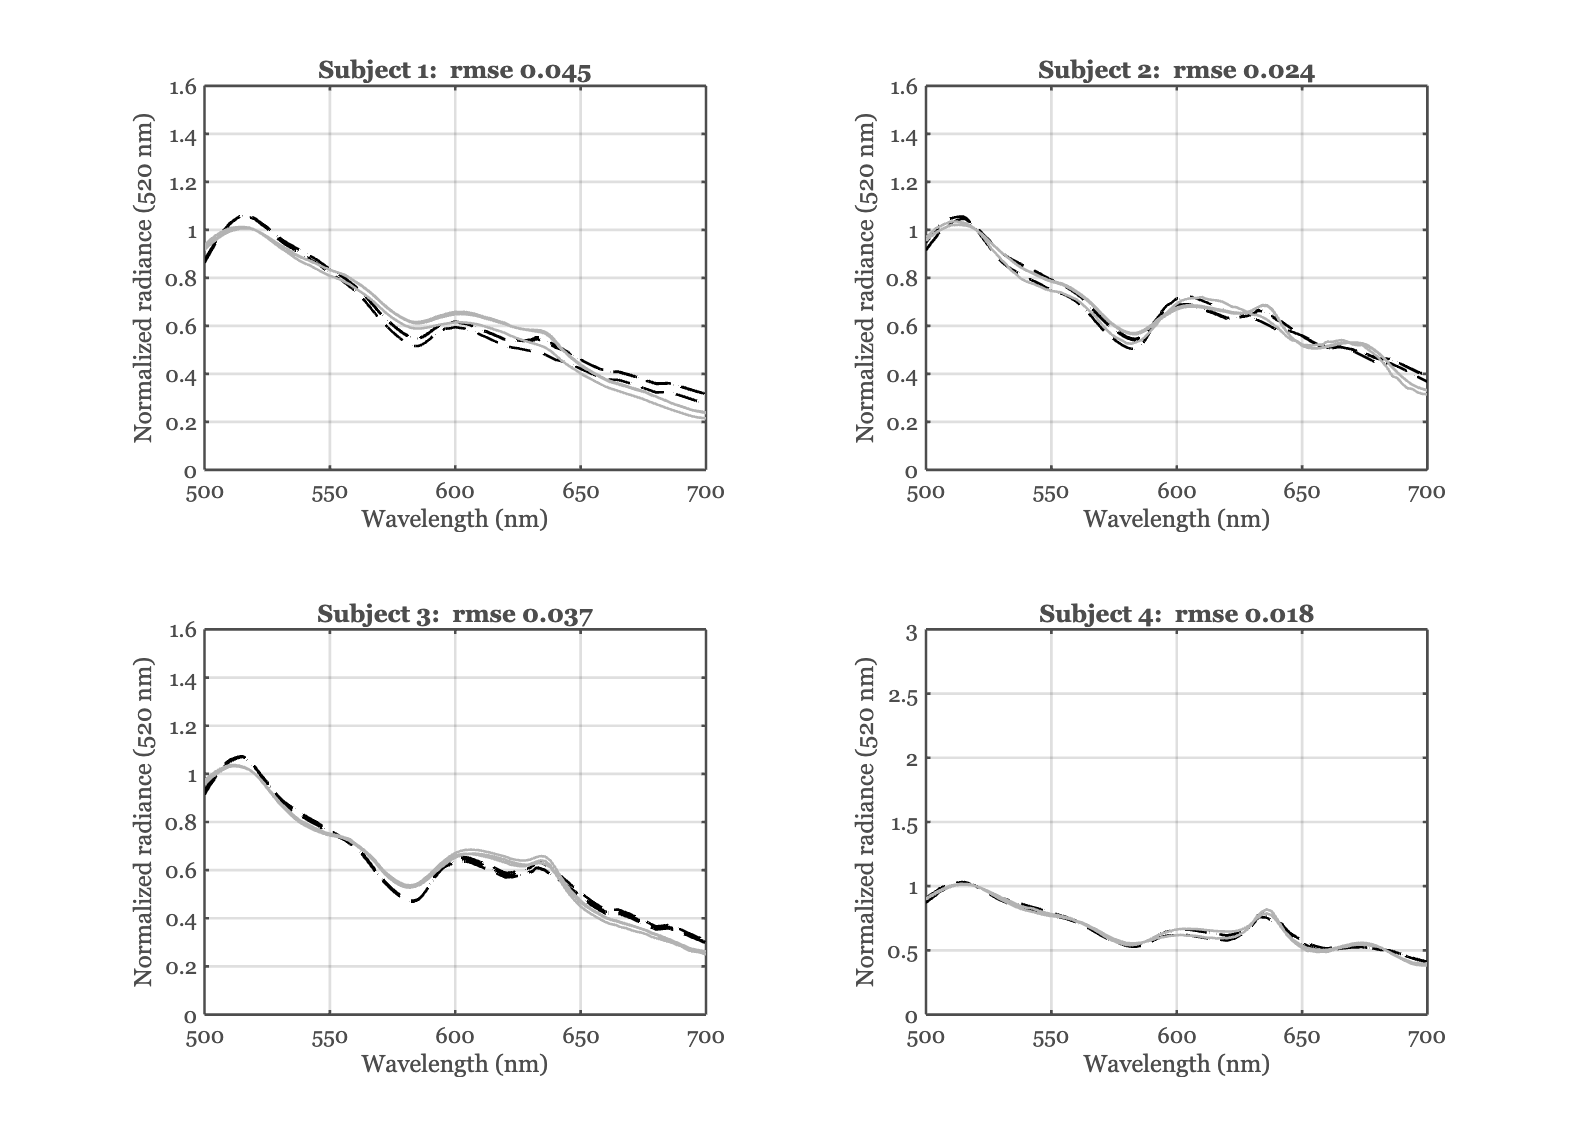

odTongue = zeros(1,numel(subjects));
nTongue450 = zeros(1,numel(subjects));
weights = cell(4,1);
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the tongue data
    tongueFiles450 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',450);
    tongueData  = oeReadFiles(tongueFiles450,'normalized wave',normWave,'wave',wave);
    nTongue450(ii) = size(tongueData,2);

    % Find the blood optical density
    [odTongue(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,tongueData,savedFluorophores);
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,tongueData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance (520 nm)');
    set(gca,'ylim',[0 1.6]);
    if ii==4, set(gca,'ylim',[0 3]); end
    title(sprintf('Subject %d:  rmse %.3f',ii,rmse(tongueData(:),predicted(:))));
end
exportgraphics(gcf,'IndividualFits-tongue450.png','Resolution',150);

### Here is the 450 nm table

fluorophoreNames = ["Collagen", "FAD", "Keratin", "Porphyrin", "Chlorophyll-a"];
oePrintModel(fluorophoreNames,odTongue,weights,nTongue450);

Subject 1 (N=3):
Blood od 17.26  Collagen: 8.90 ± 0.44 FAD: 0.72 ± 0.02 Keratin: 0.05 ± 0.02 Porphyrin: 0.00 ± 0.00 Chlorophyll-a: 0.30 ± 0.04 

Subject 2 (N=3):
Blood od 17.66  Collagen: 12.77 ± 1.87 FAD: 0.60 ± 0.00 Keratin: 0.06 ± 0.05 Porphyrin: 0.02 ± 0.01 Chlorophyll-a: 0.35 ± 0.03 

Subject 3 (N=3):
Blood od 16.80  Collagen: 13.83 ± 0.45 FAD: 0.71 ± 0.01 Keratin: 0.09 ± 0.01 Porphyrin: 0.00 ± 0.00 Chlorophyll-a: 0.20 ± 0.00 

Subject 4 (N=2):
Blood od 16.69  Collagen: 10.21 ± 1.38 FAD: 0.61 ± 0.03 Keratin: 0.24 ± 0.05 Porphyrin: 0.09 ± 0.02 Chlorophyll-a: 0.35 ± 0.01 



## Fit the lip data

For the lip, we only fit using the collagen and FAD data, adjusting for the blood.  We omit the porphyrins, chlorophyll and pseudo-keratin.

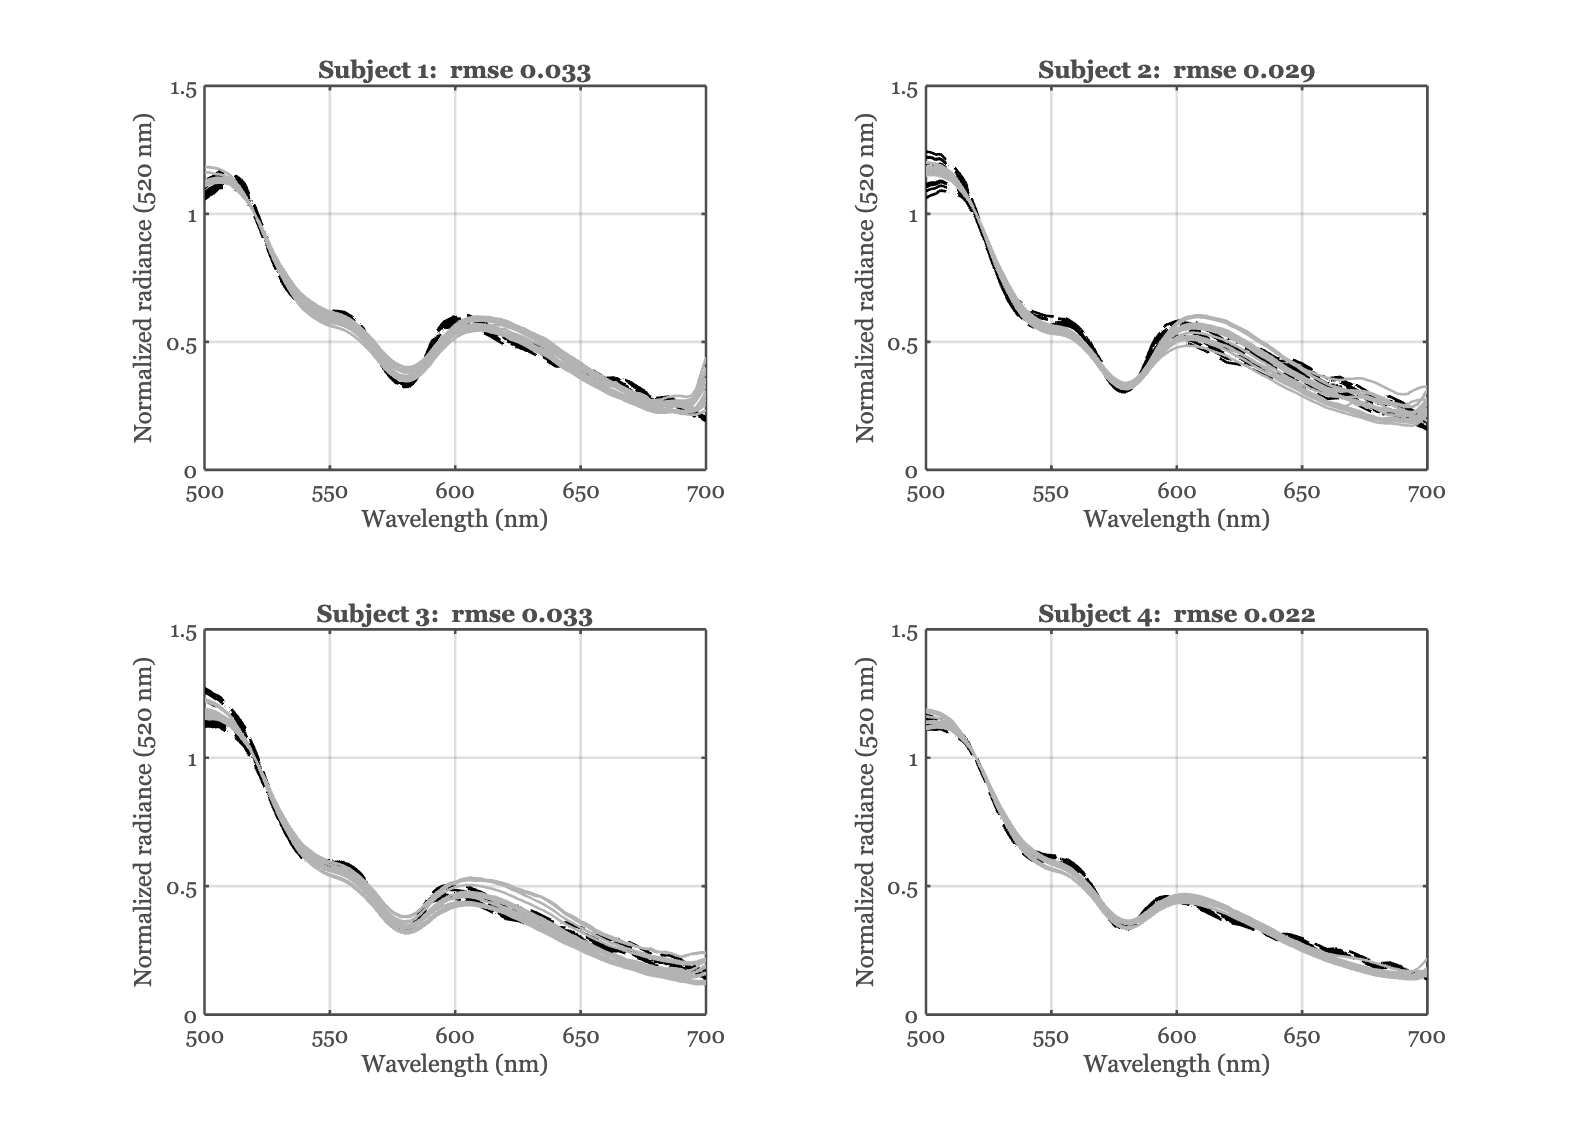

odLip = zeros(1,numel(subjects));
nLip = zeros(1,numel(subjects));
weights = cell(4,1);
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the lip data
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    lipData  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);
    nLip(ii) = size(lipData,2);

    % Find the blood optical density using only the first two columns of
    % saved fluorophores.
    [odLip(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,lipData,savedFluorophores(:,[1,2]));
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,lipData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance (520 nm)');
    set(gca,'ylim',[0 1.5]);
    title(sprintf('Subject %d:  rmse %.3f',ii,rmse(lipData(:),predicted(:))));
end
exportgraphics(gcf,'IndividualFits-lip.png','Resolution',150);

## Table of the lip weights and blood density

405 nm and 415 nm

% Print them out
fluorophoreNames = ["Collagen", "FAD"];
oePrintModel(fluorophoreNames,odLip,weights,nLip);

Subject 1 (N=14):
Blood od 11.54  Collagen: 17.34 ± 0.52 FAD: 0.63 ± 0.01 

Subject 2 (N=13):
Blood od 9.13  Collagen: 16.12 ± 1.41 FAD: 0.54 ± 0.03 

Subject 3 (N=14):
Blood od 6.32  Collagen: 13.12 ± 0.93 FAD: 0.49 ± 0.02 

Subject 4 (N=14):
Blood od 5.97  Collagen: 11.81 ± 0.38 FAD: 0.53 ± 0.02 



## Lip with the 450 nm excitation light

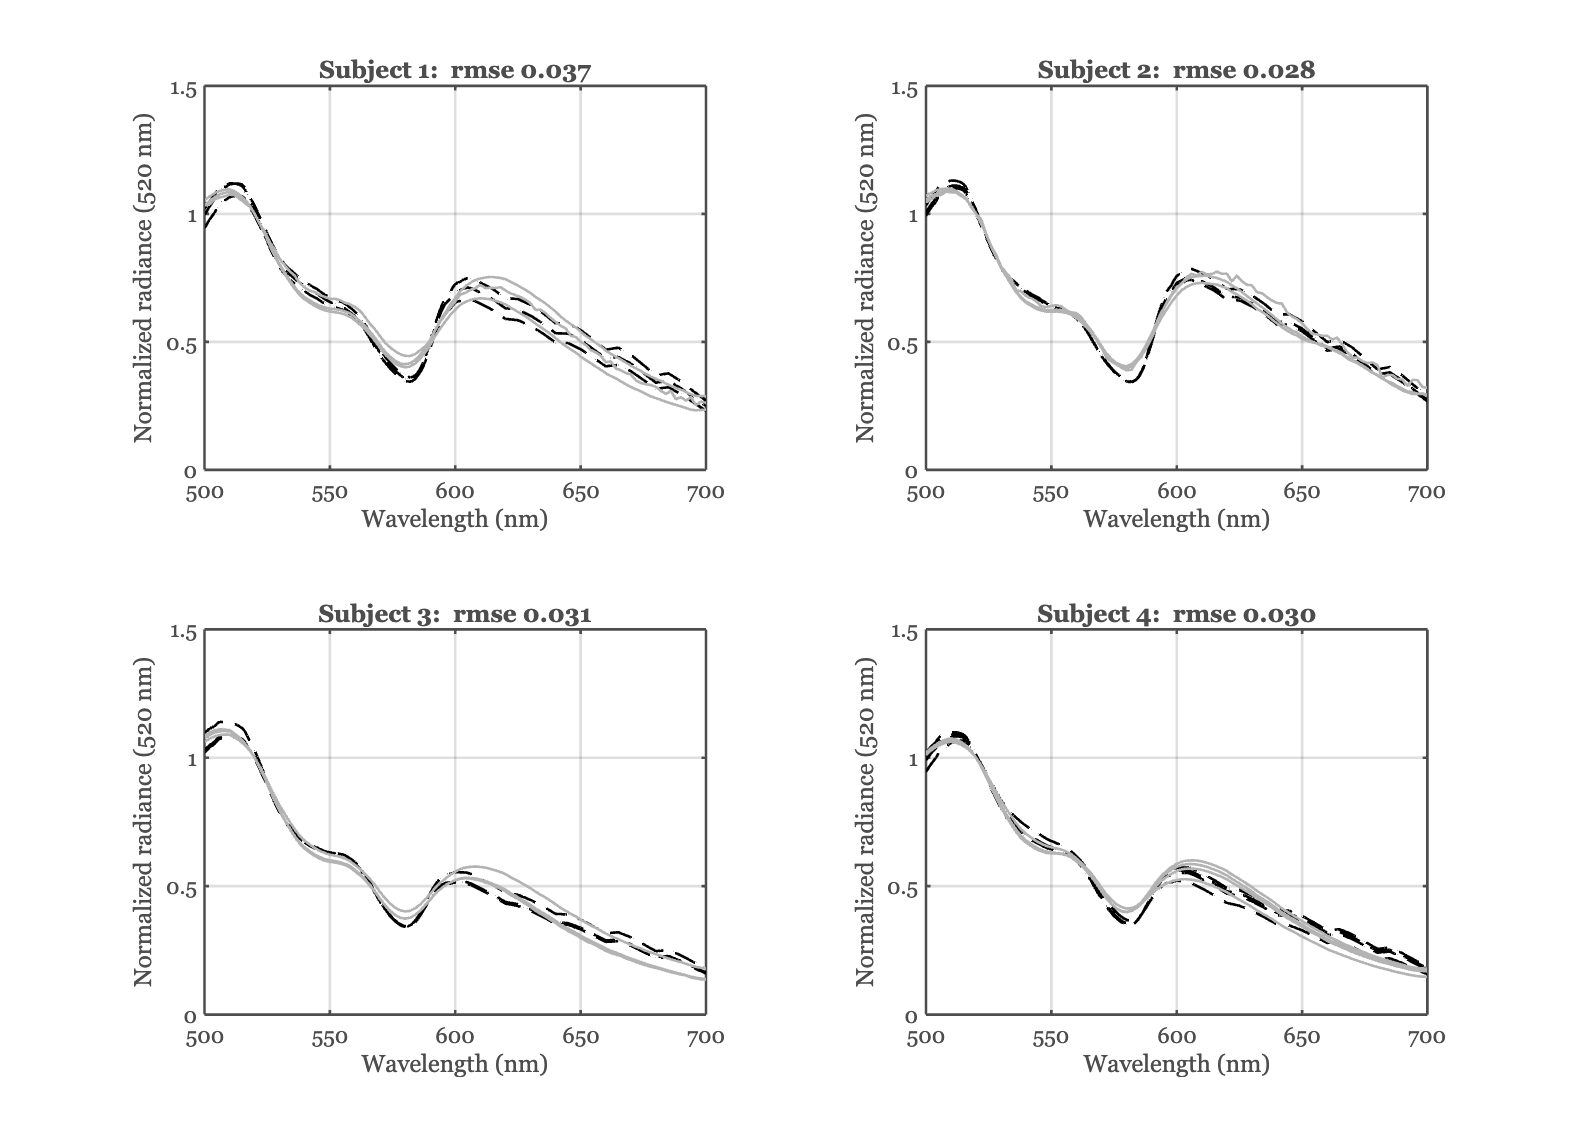

odLip = zeros(1,numel(subjects));
weights = cell(4,1);
nLip450 = zeros(1,numel(subjects));

ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the lip data
    lipFiles450 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',450);
    lipData  = oeReadFiles(lipFiles450,'normalized wave',normWave,'wave',wave);
    nLip450(ii) = size(lipData,2);

    % Find the blood optical density using only the first two columns of
    % saved fluorophores.
    [odLip(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,lipData,savedFluorophores(:,[1,2]));
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,lipData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance (520 nm)');
    set(gca,'ylim',[0 1.5]);
    title(sprintf('Subject %d:  rmse %.3f',ii,rmse(lipData(:),predicted(:))));
end
exportgraphics(gcf,'IndividualFits-lip450.png','Resolution',150);

### Table for 450 nm excitation.

fluorophoreNames = ["Collagen", "FAD"];
oePrintModel(fluorophoreNames,odLip,weights,nLip450);

Subject 1 (N=3):
Blood od 17.24  Collagen: 22.18 ± 1.81 FAD: 0.75 ± 0.02 

Subject 2 (N=3):
Blood od 17.68  Collagen: 24.61 ± 0.97 FAD: 0.73 ± 0.00 

Subject 3 (N=3):
Blood od 10.56  Collagen: 14.58 ± 0.99 FAD: 0.66 ± 0.01 

Subject 4 (N=4):
Blood od 12.70  Collagen: 15.19 ± 1.21 FAD: 0.72 ± 0.02 

